### Parameters for analysis

clear

Parameters for spectral events data:

data_path = "L:\Groups\ABCCT\EEG\T1 T2 T3 EEG\T3a_Resting";
%data_path = fullfile( 'X:','Groups','SPA','01_Data_Raw_Summary_Processed', ...
                      %'EEG','Participant_Data','03_Processed_Data' );
task      = '02_Baseline';
band      = 'beta';
method    = 2;
chans     = []; % list of chans to plot
averaging = 'spec_events'; % averaging method
time_win  = [0 5000]; % time window to use relative to stim onset (ms)
num_cyc = '_7cycles';
beapp_tag = 'HAPPE_segment_5sec';
srate = 250;
feat_to_plot = 'eventnumber'; 

Group assignment information:

group_name     = {'TD','ASD','SPD','RTT','PMS','PHTS','TSC','SYN'};
groups_to_plot = 1:2;
grp_table      = fullfile(data_path,'Group_Assignments.mat');
for g = 1:length(groups_to_plot)
    grp_folder{g} = fullfile(data_path,group_name{groups_to_plot(g)});
end

Parameters for plotting:

conds_to_inc = 0; % if a subset, 0 to include all
seg_length   = abs(sum(time_win))/1000;
plot_var     = false;
save_fig     = false;
% equal_Ns     = false;
% by_cond      = false;
% fields to extract from spec_events structs
features{1,:} = {'eventnumber','maximapowerFOM','duration','Fspan'};
if seg_length > 0
    features{2,:} = {'Event rate (Hz)','Power (FOM)','Duration (ms)','F-span (Hz)'};
else
    features{2,:} = {'Events per segment','Power (FOM)','Duration (ms)','F-span (Hz)'};
end

 

### Load & process data

## get information for plotting

load('L:\Groups\ABCCT\EEG\T1 T2 T3 EEG\T1a_Resting\segment_HAPPE_segment_5sec\A04H6847_20170811.mat', 'file_proc_info');
net = file_proc_info.net_vstruct([file_proc_info.net_10_20_elecs]);
colors = {'#4444c9','#32a852','#db4214','#a2142f','#77ac30','#edb120','#7e2f8e','#db4214'};
time_str = get_time_win_str(time_win);
chan_str = get_chan_str({},chans);
if isempty(chan_str), chan_str = '1020'; end
task_abbrevs = containers.Map({'02_Baseline','stepwise_loudness',  ...
                               'auditory_temporal_habituation', ...
                               'tactile_spatial_suppression',   ...
                               'tactile_temporal_habituation'}, ...
                               {'Resting state','SL','ATH','TSS','TTH'});
task_abb = task_abbrevs(task);

%% load group assignment table 
load(grp_table,'groups')


%% load spectral events data
n_feats = length(features{1});
% load based on averaging method
switch averaging
    %% average eeg channels first, then run spectral events
    case 'eeg'
    load_chans = strrep(int2str(chans),' ','');
    if isempty(chans)
        load_chans = '1020';
    end
    % load channel SET data
    tag = [band '_' int2str(method) '_' load_chans beapp_tag];
    %load(fullfile(data_path,task,'spec_events',[tag '.mat']),'spec_events');
    load(fullfile(data_path,'spec_events',[tag '.mat']),'spec_events');
    % sort data by group
    sorted_eeg = sort_data_by_group_old(spec_events,groups,group_name);
    clear spec_events
    
    %% run spectral events on each channel, then average outputs
    case 'spec_events'
    if isempty(chans)
        chans = [22 9 33 24 124 122 36 104 58 62 96 70 83 45 108 52 92 11];
    end
    n_chans = length(chans);
    for i_g = 1:length(groups_to_plot)
        for i_c = 1:n_chans
            % load channel SET data
            tag = [band '_' int2str(method) '_' int2str(chans(i_c)) '_' beapp_tag,'_7cycles'];
            load(fullfile(data_path,'spec_events',[tag '.mat']),'spec_events');
            %load(fullfile(grp_folder{i_g},filesep,'spec_events',[tag '.mat']),'spec_events');
            % sort data by group
            names = fieldnames(spec_events);
                for i_f = 1:size(names,1)
                    re_names{i_f} = names{i_f}(1:9);
                    n = names{i_f};
                    spec_events = renameStructField(spec_events,n,re_names{i_f});
                    clear n
                end
                
            sorted_eeg(i_c) = sort_data_by_group_SET(spec_events,groups,group_name);
            %sorted_eeg{i_g,i_c} = spec_events;
            clear spec_events
        end
        
    end
end
 %sorted_eeg = cell2struct(sorted_eeg,group_name(groups_to_plot),1);
% get subject means and standard deviations
[data_mean,data_std] = sub_avg_events_KS(sorted_eeg,features{1},conds_to_inc);

% norm the event rate
if time_win(1) == 0
time_sec = time_win(2)/1000;
for i_g = 1:length(groups_to_plot)
    for i_c = 1:n_chans
    group = group_name{groups_to_plot(i_g)};
    n_subj{i_g} = int2str(length(data_mean(1).(group).id));
    for i_s = 1: length(data_mean(i_c).(group).eventnumber)
        data_mean(i_c).(group).eventnumber(i_s) = data_mean(i_c).(group).eventnumber(i_s) / time_sec ;
        data_std(i_c).(group).eventnumber(i_s) = data_std(i_c).(group).eventnumber(i_s) / time_sec;
    end %end individual
    end %end channel
end %end group 
end

[chan_mean,chan_var] = avg_chan_topo(data_mean,data_std,features{1});

### Results

ll = 1;
ul = 1.2;
sp = tiledlayout(1,length(groups_to_plot));
sp.Title.String = ['Average Even Rate across the Scalp T3'];
for i_g = 1:length(groups_to_plot)
    gp = group_name{groups_to_plot(i_g)};
    ax(i_g) = nexttile ;
    hold(ax(i_g),'on');
    title(ax(i_g),gp)
    subtitle(ax(i_g),['n = ',num2str(n_subj{i_g})])
    for i_c = 1:n_chans
       ch_avg{i_g}(i_c,1) = chan_mean(i_c).(gp).(feat_to_plot);
       ch_var{i_g}(i_c,1) = chan_var(i_c).(gp).(feat_to_plot);
    end %end chan loop
    topoplot(ch_avg{i_g},net,'plotrad',.53,'maplimits',[ll,ul],'conv','on');
end %end group loop

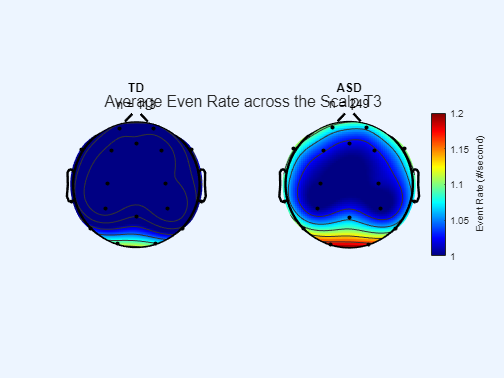

    c = colorbar ; 
    caxis([ll,ul]); 
    c.Label.String = 'Event Rate (#/second)';





% save figure
if save_fig
    pause(0.2)
    fig_path = fullfile(data_path,'figures','spec_events');
    if ~exist(fig_path,'dir'), mkdir(fig_path); end
    if plot_var
        fig_fname = [band '_groups_' chan_str '_std'];
    else
        fig_fname = [band '_groups_' chan_str '_mean'];
    end
    fig_fname = fullfile(fig_path,fig_fname);
    saveas(f,fig_fname,'jpg')
end